s=tf('s');
G=zpk(8.667/((s^2+2.36*s+8.667)))


G =
 
       1
  -----------
  (s+3) (s+1)
 
Continuous-time zero/pole/gain model.



%k=dcgain(G)

k = 0.3333

%G1=G*k


G1 =
 
    0.33333
  -----------
  (s+3) (s+1)
 
Continuous-time zero/pole/gain model.



%ep=1/(1+k)

ep = 0.7500

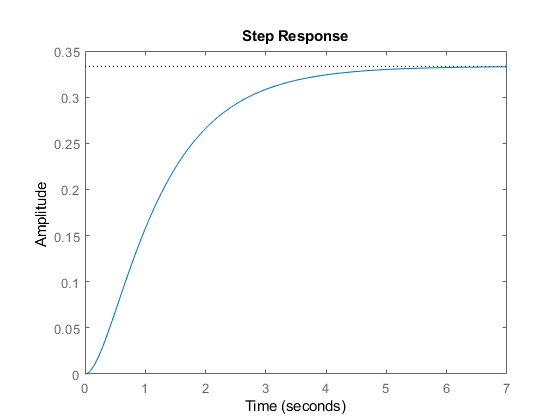

%pruebita
%dcgain(s*G1)

%step(G)

%Tc=feedback(G1,1)


Tc =
 
        0.33333
  -------------------
  (s+1.184) (s+2.816)
 
Continuous-time zero/pole/gain model.



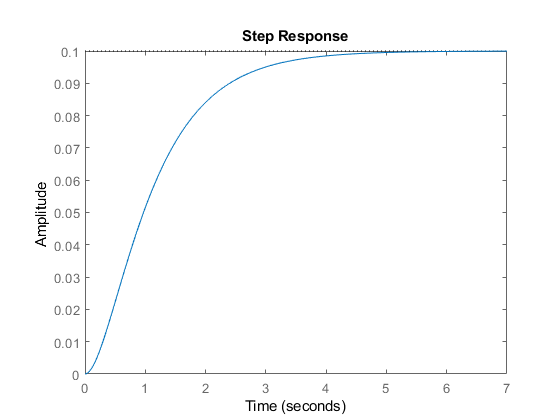

%step(Tc)


%stepinfo(Tc)

ans = struct with fields:
        RiseTime: 2.1029
    SettlingTime: 3.7653
     SettlingMin: 0.0902
     SettlingMax: 0.1000
       Overshoot: 0
      Undershoot: 0
            Peak: 0.1000
        PeakTime: 7.8156



mp=0.253

mp = 0.0500

%mp=exp((-zeta*pi)/(sqrt(1-zeta^2)))
ts=1.1648;
zeta=-log(mp)/(sqrt(pi^2+log(mp)^2))

zeta = 0.6901

Wn=4/(zeta*ts);
%ts=4/(zeta*Wn) %criterio 2%
%Wn=sqrt(600);
%M=tf(Wn^2,[1 2*zeta*Wn Wn^2])


M =
 
          3.733
  ---------------------
  s^2 + 2.667 s + 3.733
 
Continuous-time transfer function.



sigma=zeta*Wn 

sigma = 1.3333

%sigma=4/ts;
wd=2.697

wd = 1.3983

sx=-sigma+wd*i

sx = -1.3333 + 1.3983i

%Gx=10/(sx*(sx+6)*(sx+10))
Gx=2/((sx+4)*(sx+1))

Gx = -0.3036 - 0.3483i

z=1.333;
p=z+5;
cx=(sx+z)/(sx+p);
kc=1/(abs(Gx)*abs(cx))

kc = 8.0349

c=zpk(-z,-p,kc)


c =
 
  8.0349 (s+1.333)
  ----------------
     (s+6.333)
 
Continuous-time zero/pole/gain model.



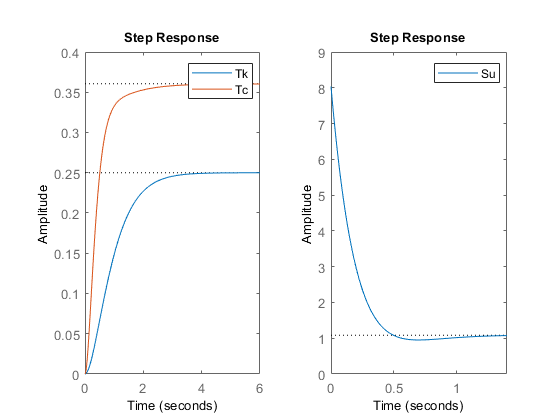


%Graficas
Tk=feedback(G,1); 
Tc=feedback(Co*G,1);
figure(2)
subplot(121),step(Tk,Tc),legend('Tk','Tc')
subplot(122),step(Tc/G),legend('Su')